===============================START=====================================


marketData = struct with fields:
       yahooDataSetUp: [1×1 YahooDataSetUp]
     spreadSheetSetUp: [1×1 SpreadSheetSetUp]
         matFileSetUp: [1×1 MatFileSetUp]
      priceVolumeData: {[3021×709 timetable]  [3021×709 timetable]  [3021×709 timetable]  [3021×709 timetable]  [3021×709 timetable]}
                 nDay: 1500
              symbols: [709×1 string]
            indexIHSG: []
            marketCap: [3021×709 timetable]
    marketCapCategory: [3021×709 timetable]
      symMarketCapRef: [709×6 table]
    marketCapRangeRef: [6×5 table]
          exhangeName: "JK"
     priceChangeLimit: [-0.3500 0.3500]
          nDayPerYear: 252


paramSetWFA = struct with fields:
                      nWalk: 1
                 lookbackUB: 300
                 nstepTrain: 240
                  nstepTest: 20
            walkPeriodTable: [1×17 table]
          walkMCapNSymTable: [1×7 timetable]
              walkMCapTable: {[1×710 timetable]  [1×710 timetable]  [1×710 timetable]  [1×710 timetable]  [1×710 timetable]  [1×710 timetable]}
                 uniqMktCap: [6×1 string]
                tradingCost: [0.0015 0.0025]
           maxCapAllocation: 0.2000
              backShiftNDay: 1
          initialAssetValue: 10000
                 maxFcnEval: 60
                      nVars: 11
          optimLookbackStep: 240
             maxDDThreshold: -0.1500
                 minPortRet: 1.1000
       minDailyRetThreshold: -0.3500
     minLast20DRetThreshold: -0.1000
     minLast60DRetThreshold: -0.0500
    minLast200DRetThreshold: 0
                  lbubConst: [11×2 double]
             minSharpeRatio: 2


MktCap: 1 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 2 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 3 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 4 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 5 | Walk: 1
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.
MktCap: 6 | Walk: 1


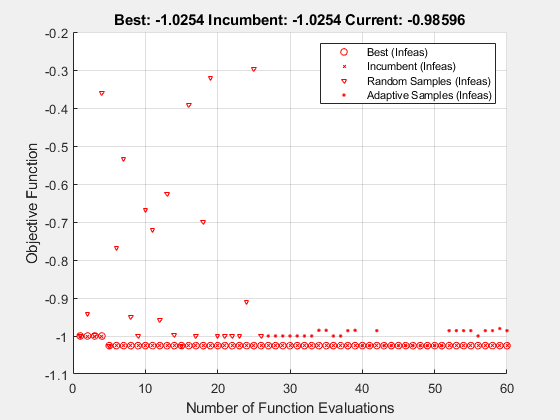

No solution found that satisfies the nonlinear constraints.


runMCapWalkTime = 576.4795

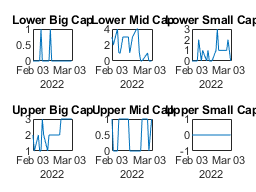

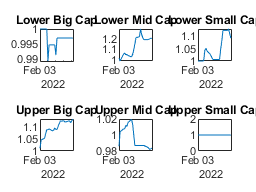

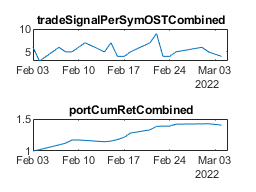

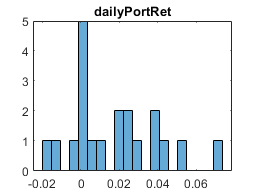

%% Start
disp("===============================START=====================================")


clear
close all
clc

%% Load the market data
yahooDataSetUp = YahooDataSetUp;
yahooDataSetUp.path = pwd;
spreadSheetSetUp = SpreadSheetSetUp;
matFileSetUp = MatFileSetUp;
matFileSetUp.path = pwd;

marketData = MarketData (yahooDataSetUp, spreadSheetSetUp, matFileSetUp);
marketData = marketData.loadDataFromMatFile;
marketData = marketData.loadSymbolMCapRef;
marketData = marketData.classifyMktCap;

marketData = struct(marketData);
dataInputPreSelect = marketData.priceVolumeData;

% prepare data for only within the target time period
startDate = datetime("01-Jan-2010", InputFormat="dd-MMM-uuuu");
endDate = datetime("31-Mar-2021", InputFormat="dd-MMM-uuuu");

dataInput = cell(1,numel(dataInputPreSelect));
for dataIdx = 1: numel(dataInputPreSelect)
    dataInput{dataIdx} = dataInputPreSelect{dataIdx}(startDate:endDate,:);
end

%% Load setting and preparation

paramSetWFA = setUpWFAParam(marketData, nWalk=18, maxFcnEval=50)

clearvars marketData dataInputPreSelect

%% runWFA
tic
mCapWalkResults = runMCapWalk(dataInput, paramSetWFA);
runMCapWalkTime = toc

% save mCapWalkResults
path = pwd;
folder = "DataOutput";
fileName = "mCapWalkResults.mat";
fullFileName = fullfile(path, folder,fileName);
save(fullFileName, "mCapWalkResults");

%% show performance evaluation
close all
combinedWFAResults = visualizeResults(mCapWalkResults, dataInput, paramSetWFA);
combinedWFAResults.summary

%% package WFAResults per symGroup and combinedResults
if exist("packageWFAResults", "var")
    clearvars packageWFAResults
end

packageWFAResults.lowBigCap             = mCapWalkResults{1} ;
packageWFAResults.lowMidCap             = mCapWalkResults{2} ;
packageWFAResults.lowSmallCap           = mCapWalkResults{3} ;
packageWFAResults.upBigCap              = mCapWalkResults{4};
packageWFAResults.upMidCap              = mCapWalkResults{5};
packageWFAResults.upSmallCap            = mCapWalkResults{6};
packageWFAResults.combinedWFAResults    = combinedWFAResults;

% save packageWFAResults
path = pwd;
folder = "DataOutput";
fileName = "packageWFAResults_Jan2020_to_Mar2021.mat";
fullFileName = fullfile(path, folder,fileName);
save(fullFileName, "packageWFAResults");

%% End
disp("===============================END=====================================")
